# Notebook 3.5: KCC Exploration of Images

This notebook will be on exploring the use of the kernel correlation for images. The idea is that this will be a faster version of the normxcorr() function that is currently used for image correlations and template matching.

## Loading in Images and References

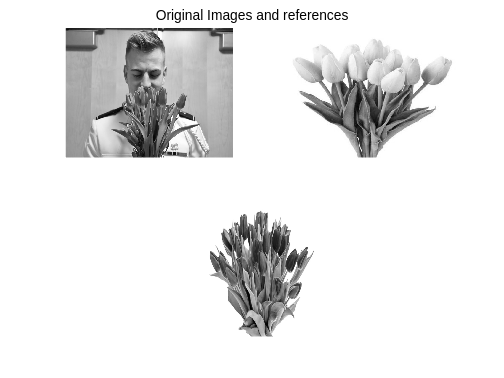

% --Setup
    clear; clc; close all; format compact;

% --Load images
    cd("/home/samkramer/Desktop/Knock Knock/Pictures/")
    tulip_original = imread("Image_1.JPG");
    tulip_reference = imread("Reference_1.jpg");
    tulip_reference_2 = imread("Tulip Reference.png");
    cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks/")

% --Convert to grayscale
    tulip_original = double(rgb2gray(tulip_original));
    tulip_reference = double(rgb2gray(tulip_reference));
    tulip_reference_2 = double(rgb2gray(tulip_reference_2));

% --Get sizes
    ref_height = size(tulip_reference, 1);
    ref_width = size(tulip_reference, 2);
    
    image_height = size(tulip_original, 1);
    image_width = size(tulip_original, 2);

% --Showing original images
    figure()
    subplot(2,2,1)
    imagesc(tulip_original)
    colormap gray
    axis off

    subplot(2,2,2)
    imagesc(tulip_reference)
    axis off

    subplot(2,3,5)
    imagesc(tulip_reference_2)
    axis off
    sgtitle("Original Images and references", 'fontsize',14)

## Calculating Image Kernels

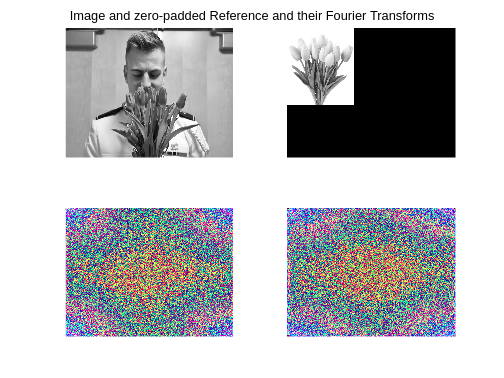

% --Making them the same sizes
    right_pad = zeros(ref_height, image_width - ref_width);
    bottom_pad = zeros(image_height - ref_height, image_width);
    reference_image = [tulip_reference, right_pad];
    reference_image = [reference_image; bottom_pad];
    
% --plot
    figure()
    subplot(2,2,1)
    imagesc(tulip_original)
        axis off
        colormap gray

    subplot(2,2,2)
    imagesc(reference_image)
        axis off
        sgtitle("Image and zero-padded Reference and their Fourier Transforms")

% --FFT of images
    f_tulip_original = fft2(tulip_original);
    f_tulip_original_db = mag2db(abs(f_tulip_original));

    f_reference_image = fft2(reference_image);
    f_reference_image_db = mag2db(abs(f_reference_image));

% --Output FFT outputs
    ax = subplot(2,2,3);
    imagesc(f_tulip_original_db)
        colormap(ax, "colorcube")
        axis off

    ax = subplot(2,2,4);
    imagesc(f_reference_image_db)
        colormap(ax, "colorcube")
        axis off

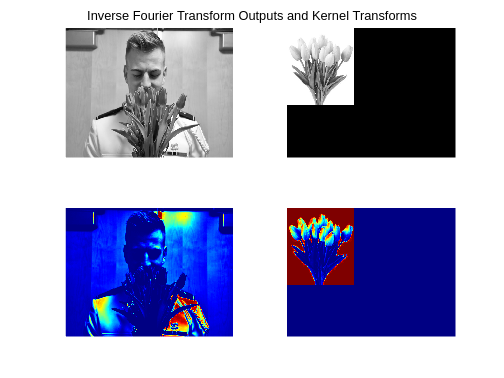

% --Inverse fourier transforms
    if_tulip_original = ifft2(f_tulip_original);
    if_reference_image = ifft2(f_reference_image);

% --Plotting images
    figure()
    subplot(2,2,1)
    imagesc(if_tulip_original)
        axis off
        colormap gray

    subplot(2,2,2)
    imagesc(if_reference_image)
        axis off
        sgtitle("Inverse Fourier Transform Outputs and Kernel Transforms")

% --Kernel Transforms of images
    k_original_image = (if_tulip_original.*if_tulip_original + 1).^3;       % Squared Kernel transformation
    k_reference_image = (if_reference_image.*if_reference_image + 1).^3;    % L-Abs Kernel transformation of images

% --Plotting
    ax = subplot(2,2,3);
    imagesc(k_original_image)
        axis off
        colormap(ax, "jet")

    ax = subplot(2,2,4);
    imagesc(k_reference_image)
        axis off
        colormap(ax, "jet")

% --Finding correlation
    kf_original = fft2(k_original_image);
    kf_reference = fft2(k_reference_image);

    correlation = kf_original .* conj(kf_reference);
    correlation = ifft2(correlation);

    m = max(max(correlation));
    [I,J] = find(correlation == m)

I = 540

J = 572

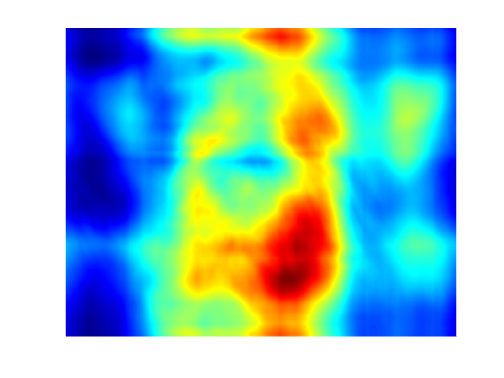

% --Showing output
    figure()
    imagesc(correlation)
        axis off
        sgtitle("")
        colormap("jet")

This is the pure correlation output and is unmapped. The peak of which occurs in a similar location as the normalizated correlation algorithm. In the Sair Lab paper, the image kernel correlator has a gaussian mapping to increase accuracy. Lets place the box around the image and then try the kernelized version of the correlator.

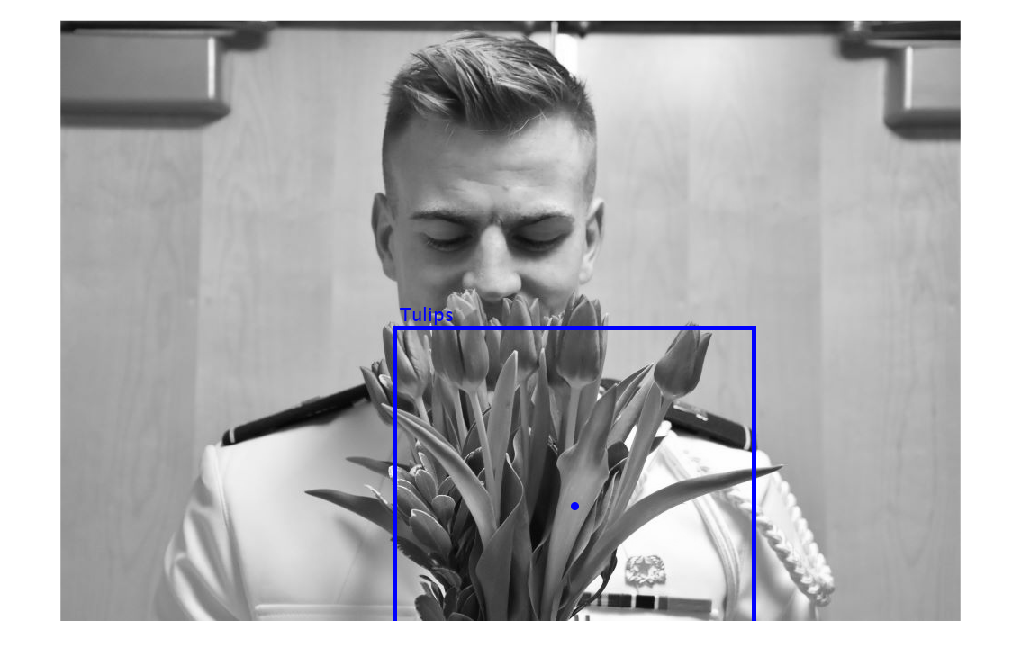

% --Putting a box around the location
    image_new = insertShape(uint8(tulip_original), "rectangle", [(J - floor(ref_width/2)), (I - floor(ref_height/2)), ref_width, ref_height], "LineWidth",5,"Color","Blue");
    image_new = insertShape(image_new, "circle",[J, I, 2], "LineWidth", 5, "Color", "Blue");
    image_new = insertText(image_new, [J - 200, I - 230], "Tulips",BoxOpacity=0,FontColor="blue",FontSize=20);
    
    figure()
    imshow(image_new)

The location of the box is pretty accurate, and is slightly shifted from the location of the normxcorr() function location, but the box location is accurate, and the max location is located in the center of the flowers. 

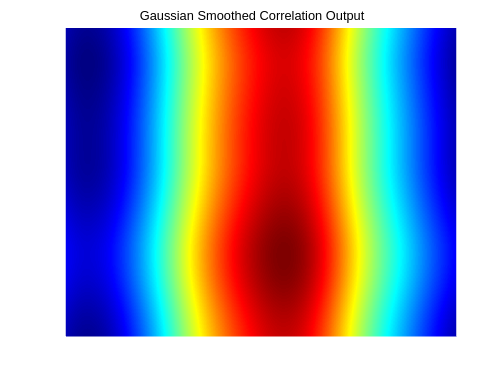

% --Gaussian Kernel of Image
    x = -image_height/2:image_height/2 - 1;
    y = -image_width/2:image_width/2 - 1;
    [X, Y] = meshgrid(y, x);
    sigma = numel(tulip_original);
    gaussian_smooth = exp((X.^2 + Y.^2)/(2*sigma));
    f_gauss_smooth = fft2(gaussian_smooth);

% --Gaussian Smoothed correlation
    correlation = kf_original .* conj(f_gauss_smooth .* kf_reference);
    correlation = ifft2(correlation);

% --output
    figure()
    imagesc(correlation)
        axis off
        sgtitle("Gaussian Smoothed Correlation Output")
        colormap jet

% --Location of the max
    m = max(max(correlation));
    [I,J] = find(correlation == m)

I = 492

J = 559

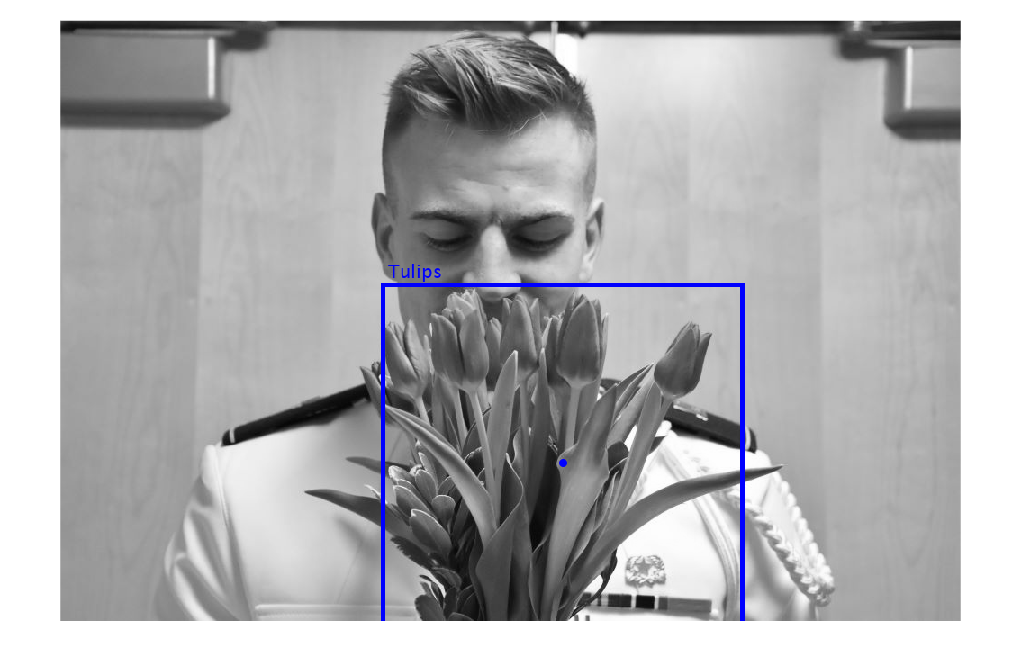

% --Locating a box on the new max point
    image_new = insertShape(uint8(tulip_original), "rectangle", [(J - floor(ref_width/2)), (I - floor(ref_height/2)), ref_width, ref_height], "LineWidth",5,"Color","Blue");
    image_new = insertShape(image_new, "circle",[J, I, 2], "LineWidth", 5, "Color", "Blue");
    image_new = insertText(image_new, [J - 200, I - 230], "Tulips",BoxOpacity=0,FontColor="blue",FontSize=20);
    
    figure()
    imshow(image_new)